## EME165 Numerical Conduction Project

Name: Alex Lewis

ID: 914825371

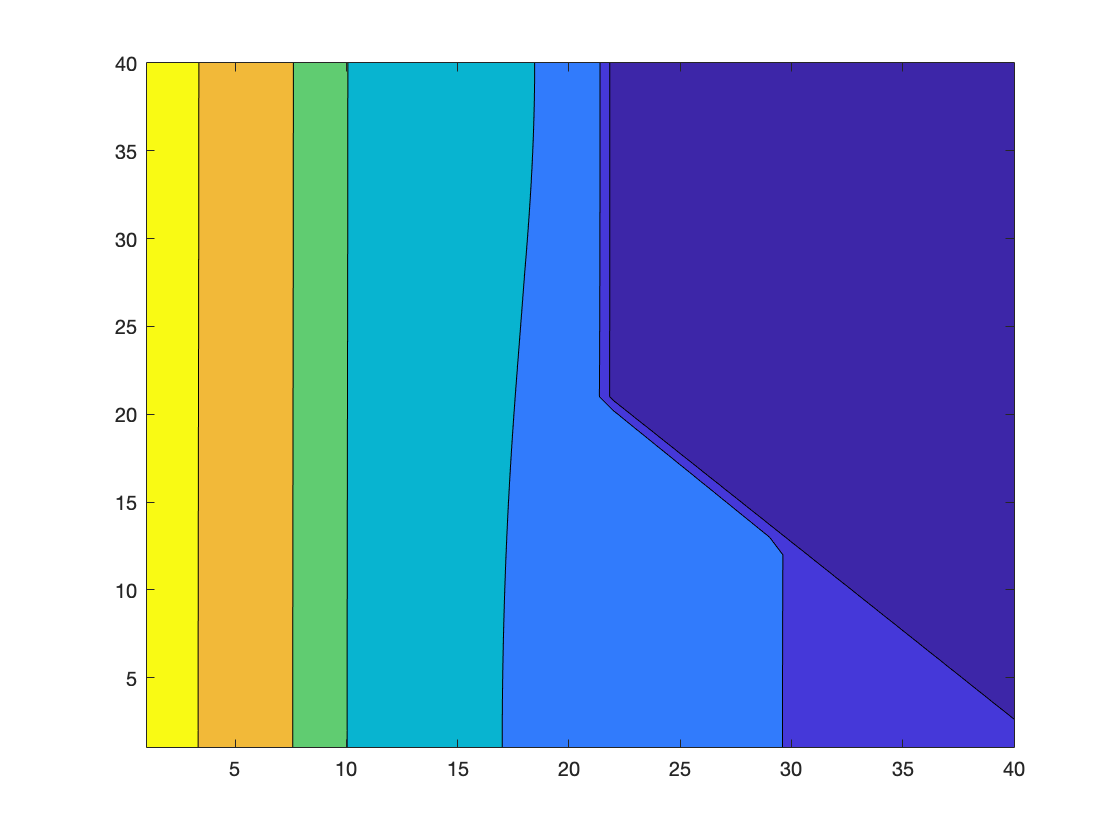

clear;
%Givens
r1 = .01; %m
r2 = .02; %m
r3 = .04; %m
L_rod = .12; %m
q_gen = 1000000; %W/m^3
H_fbase = .01; %m
S_fin = 02; %m
R_tc = .0005; %m^2K/W
R_f = .003; %m^2K/W
T_inf = 40+273.15; %K
h = 100; %W/m^2K
k_r = 2; %W/mK
k_i = 10; %W/mK
k_f = 15; %W/mK

%Node setup
N = 40; %dr direction
M = 40; %dz direction
    %Note that the nodes are choosen so that fin nodes facing the air will
    %be at the edge
dr = r3/(N-1);
dz = (L_rod/12)/(M-1);

delta_T = 1;
tolerance_T = .00003; %A very low tolerannce is necessary to get reasonable T values

T = T_inf*ones(M,N); %Assume inital temp of system is T_inf
c = 1; %iteration coutner

while delta_T>tolerance_T
    %I: Reactor
    %II: Insulation
    %III: Fin
    
    c = c+1;
    T(:,:,c) = T_inf*ones(M,N); %Most current dimension of T starts with all values = T_inf
    
    
    %I
    
    %Note that the dr index value (n) has an aditional -1 added to it. This
    %accounts for the inital nodes on paper startinng at 0,0 while Matlab
    %starts at 1,1
    
    %Reactor Corner Nodes [top and bottom left] (equations on paper were multiplied by 4 to
    %simplify)
    T(1,1,c) = (T(1,2,c-1)*(k_r*pi*dz) + T(2,1,c-1)*(.5*k_r*pi*dr^2*(1/dz)) + q_gen*(.25*pi*dr^2*dz))/ ...
                        (k_r*pi*(dz+dr^2/(2*dz)));
    T(M,1,c) = (T(M,2,c-1)*(k_r*pi*dz) + T(M-1,1,c-1)*(.5*k_r*pi*dr^2*(1/dz)) + q_gen*(.25*pi*dr^2*dz))/ ...
                        (k_r*pi*(dz+dr^2/(2*dz)));
    
    %Reactor Side Nodes [left side of reactor]
    for m=2:(M-1)
        T(m,1,c) = (T(m-1,1,c-1)*((.25*dr^2)/dz) + T(m+1,1,c-1)*((.25*dr^2)/dz) + T(m,2,c-1)*dz + q_gen*((.25*dr^2*dz)/k_r))/...
                        (dr^2/(2*dz)+dz);
    end
    
    %Reactor Boundry Nodes [top and bottom]
    for n=2:(N/4)
        T(1,n,c) = (T(1,n-1,c-1)*(n-1.5) + T(1,n+1,c-1)*(n-.5) + T(2,n,c-1)*(2*(n-1)*dr^2*dz^-2) + q_gen*(((n-1)*dr^2)/k_r))/...
                        (2*(n-1)*(1+dr^2/dz^2));
        T(M,n,c) = (T(M,n-1,c-1)*(n-1.5) + T(M,n+1,c-1)*(n-.5) + T(M-1,n,c-1)*(2*(n-1)*dr^2*dz^-2) + q_gen*(((n-1)*dr^2)/k_r))/...
                        (2*(n-1)*(1+dr^2/dz^2));
    end
    
    %Reactor Interior Nodes
    for m=2:(M-1)
        for n=2:(N/4)
            T(m,n,c) = (T(m,n-1,c-1)*((n-1.5)*dz) + T(m,n+1,c-1)*(n-.5)*dz + (n-1)*(dr^2/dz)*(T(m+1,n,c-1)+T(m-1,n,c-1)) + q_gen*(((n-1)*dr^2*dz)/k_r))/...
                        (2*(n-1)*(dz+dr^2/dz));
        end
    end
    
    
    
    %I and II
    
    %Boundry half Nodes at Reactor and Insulation Interface
    T(1,N/4+1,c) = (T(1,N/4,c-1)*(.5*k_r*pi*dz*(N/4-.5)) + T(1,N/4+2,c-1)*.5*pi*k_i*dz*(N/4+.5) + (T(2,N/4+1,c-1)*.5*pi*(N/4)*dr^2*(k_r+k_i))/dz + q_gen*.25*pi*(N/4)*dr^2*dz)/ ... 
                    (.5*pi*dz*(k_r*(N/4-.5) + k_i*(N/4+.5)) + (.5*pi*(N/4)*dr^2*(k_r+k_i))/dz);
    T(M,N/4+1,c) = (T(M,N/4,c-1)*(.5*k_r*pi*dz*(N/4+.5)) + T(M,N/4+2,c-1)*.5*k_i*pi*dz*(N/4+1.5) + (T(M-1,N/4+1,c-1)*.5*pi*(N/4+1)*dr^2*(k_r+k_i))/dz + q_gen*.25*pi*(N/4+1)*dr^2*dz)/ ... 
                    (.5*pi*dz*(k_r*(N/4+.5) + k_i*(N/4+1.5)) + (.5*pi*(N/4+1)*dr^2*(k_r+k_i))/dz);
            
    %Nodes at Interface between Reactor and Insulation
    for m=2:M-1
        T(m,N/4+1,c) = (T(m,N/4,c-1)*k_r*(N/4-.5) + T(m,N/4+2,c-1)*k_i*(N/4+.5) + T(m+1,N/4+1,c-1)*(N/4)*.5*dr^2*dz^-2*(k_r+k_i) + T(m-1,N/4+1,c-1)*(N/4)*.5*dr^2*dz^-2*(k_r+k_i) + q_gen*(N/4)*.5*dr^2)/ ...
                        (k_r*(N/4-.5)+k_i*(N/4+.5)+(N/4)*dr^2*dz^-2*(k_r+k_i));
    end
    
    
    
    %II
    
    %Insulation Boundry Nodes [top and bottom]. Note that they are the same
    %equations as I, but with different k
    for n=N/4+2:(N/2)
        T(1,n,c) = (T(1,n-1,c-1)*(n-1.5) + T(1,n+1,c-1)*(n-.5) + T(2,n,c-1)*(2*(n-1)*dr^2*dz^-2))/...
                        (2*(n-1)*(1+dr^2/dz^2));
        T(M,n,c) = (T(M,n-1,c-1)*(n-1.5) + T(M,n+1,c-1)*(n-.5) + T(M-1,n,c-1)*(2*(n-1)*dr^2*dz^-2))/...
                        (2*(n-1)*(1+dr^2/dz^2));
    end
    
    %Interior Nodes of Insulation
    for m=2:(M-1)
        for n=N/4+2:(N/2)
            T(m,n,c) = (T(m,n-1,c-1)*((n-1.5)*dz) + T(m,n+1,c-1)*(n-.5)*dz + (n-1)*(dr^2/dz)*(T(m+1,n,c-1) + T(m-1,n,c-1)))/...
                            (2*(n-1)*(dz+dr^2/dz));
        end
    end
    
    %Corner Node of Insulation Facing Fin
    T(1,N/2+1,c) = (T(1,N/2,c-1)*k_i*dz*(N/2-.5) + T(2,N/2+1,c-1)*k_i*(N/2)*dr^2*dz^-1 + T(1,N/2+2,c-1)*dr*dz*(N/2)/(R_tc))/...
                        (k_i*dz*(N/2-.5) + k_i*(N/2)*dr^2*dz^-1 + (dr*dz*(N/2))/R_tc);
    
    %Boundry Nodes of Insulaiton Facing Fin
    for m=2:M/2
        T(m,N/2+1,c) = (T(m-1,N/2+1,c-1)*(N/2)*dr^2 + T(m+1,N/2+1,c-1)*(N/2)*dr^2 + T(m,N/2,c-1)*2*dz^2*(N/2-.5) + (T(m,N/2+2,c-1)*2*dz^2*dr*(N/2))/(k_i*R_tc))/...
                        (2*(N/2)*dr^2 + 2*dz^2*(N/2-.5) + (2*dz^2*dr*(N/2))/(k_i*R_tc));
    end
    
    %Boundry Nodes of Insulation w/o fin [facing air with convection]
    for m=(M/2+1):M-1
        T(m,N/2+1,c) = (T(m-1,N/2+1,c-1)*(N/2)*dr^2 + T(m+1,N/2+1,c-1)*(N/2)*dr^2 + T(m,N/2,c-1)*2*dz^2*(N/2-.5) + T_inf*(h/k_i)*2*(N/2)*dr*dz^2)/...
                        (N*dr^2 + 2*dz^2*(N/2-.5) + (N/k_i)*h*dr*dz^2);
    end
    
    %Corner Node of Insulation w/o fin [facing air with convection]
    T(M,N/2+1,c) = (T(M,N/2,c-1)*k_i*dz*(N/2-.5) + (T(m-1,N/2+1,c-1)*k_i*(N/2)*dr^2)/dz + T_inf*h*(N/2)*dr*dz)/...
                        (k_i*dz*(N/2-.5) + (dr^2*(N/2)*k_i)/(dz) + h*(N/2)*dr*dz);
    
        
                    
    %III
    
    %Note that the dr index (n) is now subtracted by 2 to account for the
    %shift from 0,0 inital point to matlab's 1,1 inital point AND the fact
    %that there are two nodes at the same dr location. Those two nodes that
    %share the same location are at the fin and insulation interface.
    
    %Boundry Nodes on Fin next to Insulation (w/ contact resistance)
    for m=2:M/2-1
        T(m,N/2+2,c) = (T(m-1,N/2+2,c-1)*(N/2)*dr^2 + T(m+1,N/2+2,c-1)*(N/2)*dr^2 + T(m,N/2+3,c-1)*2*dz^2*(N/2+.5) + (T(m,N/2+1,c-1)*2*dz^2*dr*(N/2))/(k_f*R_tc))/...
                        (2*(N/2)*dr^2 + 2*dz^2*(N/2+.5) + (2*dz^2*dr*(N/2))/(k_f*R_tc));
    end
    
    %Corner Node of Fin Facing Facing Insulation
    T(1,N/2+2,c) = (T(1,N/2+3,c-1)*k_f*dz*(N/2+.5) + (T(2,N/2+2,c-1)*k_f*(N/2)*dr^2)/dz + T(1,N/2+1,c-1)*dr*dz*(N/2)/(R_tc))/...
                        (k_f*dz*(N/2+.5) + (k_f*(N/2)*dr^2)/dz + (dr*dz*(N/2))/R_tc);

    %Boundry Nodes alongside bottom portion fin (Using insulation boundry
    %node equation w/ different indexing and k)
    for n=N/2+3:(N-1)
        T(1,n,c) = (T(1,n-1,c-1)*(n-2.5) + T(1,n+1,c-1)*(n-1.5) + T(2,n,c-1)*(2*(n-2)*dr^2*dz^-2))/...
                        (2*(n-2)*(1+dr^2/dz^2));
    end
    
    %Because of the weird indexing issues discussed earlier, the node at
    %the very tip does not lie within the actual T matrix. T_tip is
    %calculated individually here.
    T_tip = (T(1,N,c-1)*.5*k_f*(N-.5)*dz + T_inf*h*dr*dz*2*(N-.5))/ ...
                                 (.5*k_f*(N-.5)*dz + h*dr*dz*2*(N-.5));
   
    %Here is the equation for bottom boundry node next to T_tip. it is not
    %included in the for loop listed above to acount for T_tip not being in
    %the T matrix.
    T(1,N,c) = (T(1,N-1,c-1)*(N-1.5) + T_tip*(N-.5) + T(2,N,c-1)*(2*(N-1)*dr^2*dz^-2))/...
                        (2*(N-1)*(1+dr^2/dz^2));

    %Fin Top Corner node (Trianle tip w/ contact resistance)
    T(M/2,N/2+2,c) = (T(M/2-1,N/2+2,c-1)*.5*k_f*(N/2)*dr^2*dz^-1 + (T(M/2,N/2+1,c-1)*(N/2)*dz*dr)/(2*R_tc) + T_inf*(h*dr*dz*2*(N/2)))/ ...
                            (.5*k_f*(N/2)*dr^2*(1/dz) + (N/2)*.5*dz*dr*(1/R_tc) + h*dr*dz*2*(N/2));
                        
    %Fin Nodes Facing the Air [triangle nodes]
    n=23;
    for m= M/2-1:-1:2
        T(m,n,c) = (T(m,n-1,c-1)*(n-2.5)*dz + (T(m-1,n,c-1)*(n-2)*dr^2)/dz + T_inf*4*(h/k_f)*dr*dz*(n-2.5))/ ...
                         ((n-2.5)*dz + ((n-2)*dr^2)/dz + 4*(h/k_f)*dr*dz*(n-2.5));
        n=n+1; %n increases every time m decreases to acount for the slope of the fin
        
    end
             
    %Innterior nodes of fin
    mm=M/2-1;
    for n=N/2+3:N-1
        mm=mm-1;
        for m=2:mm
            T(m,n,c) = (T(m,n-1,c-1)*(n-2.5)*dz + T(m,n+1,c-1)*(n-1.5)*dz + (n-2)*(dr^2/dz)*(T(m+1,n,c-1)+T(m-1,n,c-1)))/(2*(n-2)*(dz+dr^2/dz));
            
        end
        
    end
                        
    
    delta_T = max(max(abs(T(:,:,c)-T(:,:,c-1))));
    T(:,:,c-1)=zeros(M,N); %Remove all values from previous matrix to accomidate incredibly 
                            %small tolerance.
end

%Ploting the control volume being analyzed and entire reactor
T_final=T(:,:,c);
T(:,:,:)=[];
contourf(T_final)

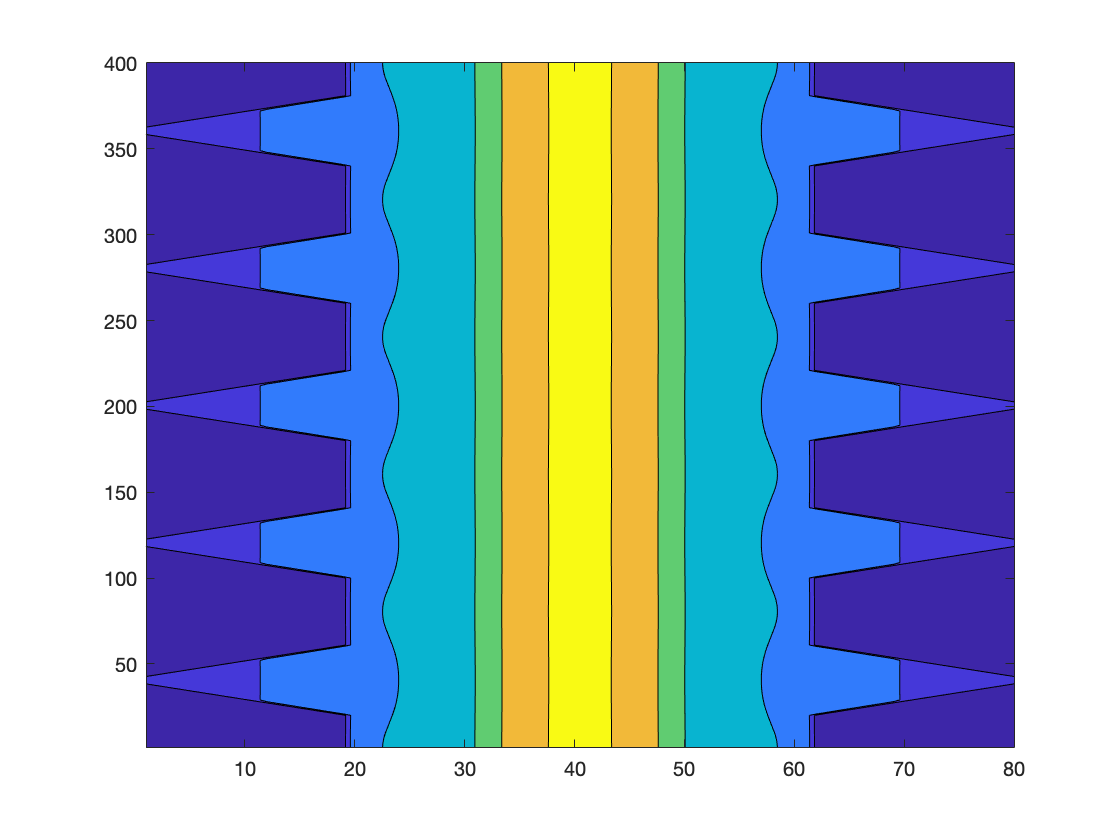

y=flip(T_final,2);
z=[flip(y,1),flip(T_final,1);y,T_final;flip(y,1),flip(T_final,1);y,T_final;flip(y,1),flip(T_final,1);y,T_final;flip(y,1),flip(T_final,1);y,T_final;flip(y,1),flip(T_final,1);y,T_final];
contourf(z)

%finding q off insulation:
q1=[];
index = 1;


%looping through the convective boundry nodes
for m=M/2+1:M-1
    q1(index)= (T_final(m,N/2+1)-T_inf)*h*pi*dr*(N/2)*dz;
    index=index+1;
end
%including the final boundry node of the insulation
q1(index+1) = (T_final(M,N/2+1)-T_inf)*h*pi*dr*(N/2)*(dz/2);

%Note that q_base is q from insulation
q_base = sum(q1) %this is for one C.V.

q_base = 0.3628

q_base_total = 2*12*q_base %This is for the whole reactor (One C.V. is a half fin and 

q_base_total = 8.7069

                       %half cylinder. There are six fins and another half
                       %to account for)

                       
%Finding q off fin:
q2=[];
n=23;

%Looping through all of the full fin nodes
for m= M/2-1:-1:2
    q2(index)=(T_final(m,n)-T_inf)*h*pi*(n-2)*dr*4*dz;
    n=n+1;
    index=index+1;
end

%Including the tip node and trianglar finn node at the insulation face.
q2(index+1) = (T_tip-T_inf)*h*pi*(n-2)*dr*2*dz;
q2(index+2) = (T_final(M/2,N/2+2)-T_inf)*h*pi*(n-2)*dr*2*dz;

%Note that q_f is q from fin
q_f = sum(q2) %Just one C.V.

q_f = 1.2134

q_f_total = 2*12*q_f %For the entire reactor

q_f_total = 29.1212

## Bonus Question:

Note that the above code for the reactor without the fowling will be used here with the exception of new equations for 

the parts exposed to convection. Scroll down to the %%%%%NEWCODE%%%%% sections. 

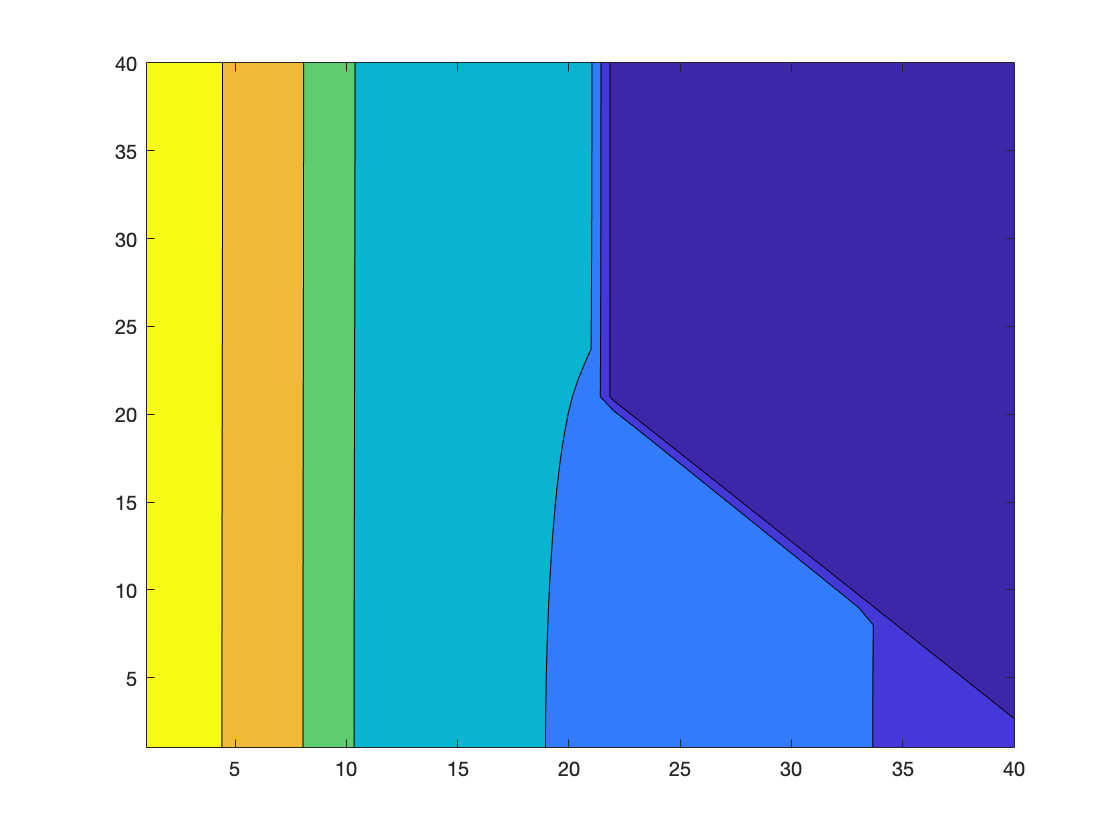

clear;
%Givens
r1 = .01; %m
r2 = .02; %m
r3 = .04; %m
L_rod = .12; %m
q_gen = 1000000; %W/m^3
H_fbase = .01; %m
S_fin = 02; %m
R_tc = .0005; %m^2K/W
R_f = .003; %m^2K/W
T_inf = 40+273.15; %K
h = 100; %W/m^2K
k_r = 2; %W/mK
k_i = 10; %W/mK
k_f = 15; %W/mK

%Node setup
N = 40; %dr direction
M = 40; %dz direction
    %Note that the nodes are choosen so that fin nodes facing the air will
    %be at the edge
dr = r3/(N-1);
dz = (L_rod/12)/(M-1);

delta_T = 1;
tolerance_T = .000000001; %A very low tolerannce is necessary to get reasonable T values

T = T_inf*ones(M,N); %Assume inital temp of system is T_inf
c = 1; %iteration coutner

while delta_T>tolerance_T
    %I: Reactor
    %II: Insulation
    %III: Fin
    
    c = c+1;
    T(:,:,c) = T_inf*ones(M,N); %Most current dimension of T starts with all values = T_inf
    
    
    %I
    
    %Note that the dr index value (n) has an aditional -1 added to it. This
    %accounts for the inital nodes on paper startinng at 0,0 while Matlab
    %starts at 1,1
    
    %Reactor Corner Nodes [top and bottom left] (equations on paper were multiplied by 4 to
    %simplify)
    T(1,1,c) = (T(1,2,c-1)*(k_r*pi*dz) + T(2,1,c-1)*(.5*k_r*pi*dr^2*(1/dz)) + q_gen*(.25*pi*dr^2*dz))/ ...
                        (k_r*pi*(dz+dr^2/(2*dz)));
    T(M,1,c) = (T(M,2,c-1)*(k_r*pi*dz) + T(M-1,1,c-1)*(.5*k_r*pi*dr^2*(1/dz)) + q_gen*(.25*pi*dr^2*dz))/ ...
                        (k_r*pi*(dz+dr^2/(2*dz)));
    
    %Reactor Side Nodes [left side of reactor]
    for m=2:(M-1)
        T(m,1,c) = (T(m-1,1,c-1)*((.25*dr^2)/dz) + T(m+1,1,c-1)*((.25*dr^2)/dz) + T(m,2,c-1)*dz + q_gen*((.25*dr^2*dz)/k_r))/...
                        (dr^2/(2*dz)+dz);
    end
    
    %Reactor Boundry Nodes [top and bottom]
    for n=2:(N/4)
        T(1,n,c) = (T(1,n-1,c-1)*(n-1.5) + T(1,n+1,c-1)*(n-.5) + T(2,n,c-1)*(2*(n-1)*dr^2*dz^-2) + q_gen*(((n-1)*dr^2)/k_r))/...
                        (2*(n-1)*(1+dr^2/dz^2));
        T(M,n,c) = (T(M,n-1,c-1)*(n-1.5) + T(M,n+1,c-1)*(n-.5) + T(M-1,n,c-1)*(2*(n-1)*dr^2*dz^-2) + q_gen*(((n-1)*dr^2)/k_r))/...
                        (2*(n-1)*(1+dr^2/dz^2));
    end
    
    %Reactor Interior Nodes
    for m=2:(M-1)
        for n=2:(N/4)
            T(m,n,c) = (T(m,n-1,c-1)*((n-1.5)*dz) + T(m,n+1,c-1)*(n-.5)*dz + (n-1)*(dr^2/dz)*(T(m+1,n,c-1)+T(m-1,n,c-1)) + q_gen*(((n-1)*dr^2*dz)/k_r))/...
                        (2*(n-1)*(dz+dr^2/dz));
        end
    end
    
    
    
    %I and II
    
    %Boundry half Nodes at Reactor and Insulation Interface
    T(1,N/4+1,c) = (T(1,N/4,c-1)*(.5*k_r*pi*dz*(N/4-.5)) + T(1,N/4+2,c-1)*.5*pi*k_i*dz*(N/4+.5) + (T(2,N/4+1,c-1)*.5*pi*(N/4)*dr^2*(k_r+k_i))/dz + q_gen*.25*pi*(N/4)*dr^2*dz)/ ... 
                    (.5*pi*dz*(k_r*(N/4-.5) + k_i*(N/4+.5)) + (.5*pi*(N/4)*dr^2*(k_r+k_i))/dz);
    T(M,N/4+1,c) = (T(M,N/4,c-1)*(.5*k_r*pi*dz*(N/4+.5)) + T(M,N/4+2,c-1)*.5*k_i*pi*dz*(N/4+1.5) + (T(M-1,N/4+1,c-1)*.5*pi*(N/4+1)*dr^2*(k_r+k_i))/dz + q_gen*.25*pi*(N/4+1)*dr^2*dz)/ ... 
                    (.5*pi*dz*(k_r*(N/4+.5) + k_i*(N/4+1.5)) + (.5*pi*(N/4+1)*dr^2*(k_r+k_i))/dz);
            
    %Nodes at Interface between Reactor and Insulation
    for m=2:M-1
        T(m,N/4+1,c) = (T(m,N/4,c-1)*k_r*(N/4-.5) + T(m,N/4+2,c-1)*k_i*(N/4+.5) + T(m+1,N/4+1,c-1)*(N/4)*.5*dr^2*dz^-2*(k_r+k_i) + T(m-1,N/4+1,c-1)*(N/4)*.5*dr^2*dz^-2*(k_r+k_i) + q_gen*(N/4)*.5*dr^2)/ ...
                        (k_r*(N/4-.5)+k_i*(N/4+.5)+(N/4)*dr^2*dz^-2*(k_r+k_i));
    end
    
    
    
    %II
    
    %Insulation Boundry Nodes [top and bottom]. Note that they are the same
    %equations as I, but with different k
    for n=N/4+2:(N/2)
        T(1,n,c) = (T(1,n-1,c-1)*(n-1.5) + T(1,n+1,c-1)*(n-.5) + T(2,n,c-1)*(2*(n-1)*dr^2*dz^-2))/...
                        (2*(n-1)*(1+dr^2/dz^2));
        T(M,n,c) = (T(M,n-1,c-1)*(n-1.5) + T(M,n+1,c-1)*(n-.5) + T(M-1,n,c-1)*(2*(n-1)*dr^2*dz^-2))/...
                        (2*(n-1)*(1+dr^2/dz^2));
    end
    
    %Interior Nodes of Insulation
    for m=2:(M-1)
        for n=N/4+2:(N/2)
            T(m,n,c) = (T(m,n-1,c-1)*((n-1.5)*dz) + T(m,n+1,c-1)*(n-.5)*dz + (n-1)*(dr^2/dz)*(T(m+1,n,c-1) + T(m-1,n,c-1)))/...
                            (2*(n-1)*(dz+dr^2/dz));
        end
    end
    
    %Corner Node of Insulation Facing Fin
    T(1,N/2+1,c) = (T(1,N/2,c-1)*k_i*dz*(N/2-.5) + T(2,N/2+1,c-1)*k_i*(N/2)*dr^2*dz^-1 + T(1,N/2+2,c-1)*dr*dz*(N/2)/(R_tc))/...
                        (k_i*dz*(N/2-.5) + k_i*(N/2)*dr^2*dz^-1 + (dr*dz*(N/2))/R_tc);
    
    %Boundry Nodes of Insulaiton Facing Fin
    for m=2:M/2
        T(m,N/2+1,c) = (T(m-1,N/2+1,c-1)*(N/2)*dr^2 + T(m+1,N/2+1,c-1)*(N/2)*dr^2 + T(m,N/2,c-1)*2*dz^2*(N/2-.5) + (T(m,N/2+2,c-1)*2*dz^2*dr*(N/2))/(k_i*R_tc))/...
                        (2*(N/2)*dr^2 + 2*dz^2*(N/2-.5) + (2*dz^2*dr*(N/2))/(k_i*R_tc));
    end
    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%NEWCODE%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %Boundry Nodes of Insulation w/o fin [facing air with convection]
    for m=(M/2+1):M-1
        R_eqi_bound = R_f/(pi*(N/2)*dr*dz) + 1/(h*pi*(N/2)*dr*dz);
        %Multiply paper equations by 2dz to simplify
        T(m,N/2+1,c) = (T(m-1,N/2+1,c-1)*(N/2)*dr^2 + T(m+1,N/2+1,c-1)*(N/2)*dr^2 + T(m,N/2,c-1)*2*dz^2*(N/2-.5) + (T_inf*2*dz)/(k_i*pi*R_eqi_bound))/...
                        (N*dr^2 + 2*dz^2*(N/2-.5) + (2*dz)/(k_i*pi*R_eqi_bound));
    end
    
    %Corner Node of Insulation w/o fin [facing air with convection]
    %Multiply paper equations by 2
    R_eqi_corner = (2*R_f)/(pi*(N/2)*dr*dz) + 2/(h*pi*(N/2)*dr*dz);
    T(M,N/2+1,c) = (T(M,N/2,c-1)*dz*(N/2-.5) + (T(m-1,N/2+1,c-1)*(N/2)*dr^2)/dz + (T_inf*2)/(k_i*pi*R_eqi_corner))/...
                        (dz*(N/2-.5) + (dr^2*(N/2))/(dz) + 2/(k_i*pi*R_eqi_corner));
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%ENDNEWCODE%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
                    
    %III
    
    %Note that the dr index (n) is now subtracted by 2 to account for the
    %shift from 0,0 inital point to matlab's 1,1 inital point AND the fact
    %that there are two nodes at the same dr location. Those two nodes that
    %share the same location are at the fin and insulation interface.
    
    %Boundry Nodes on Fin next to Insulation (w/ contact resistance)
    for m=2:M/2-1
        T(m,N/2+2,c) = (T(m-1,N/2+2,c-1)*(N/2)*dr^2 + T(m+1,N/2+2,c-1)*(N/2)*dr^2 + T(m,N/2+3,c-1)*2*dz^2*(N/2+.5) + (T(m,N/2+1,c-1)*2*dz^2*dr*(N/2))/(k_f*R_tc))/...
                        (2*(N/2)*dr^2 + 2*dz^2*(N/2+.5) + (2*dz^2*dr*(N/2))/(k_f*R_tc));
    end
    
    %Corner Node of Fin Facing Facing Insulation
    T(1,N/2+2,c) = (T(1,N/2+3,c-1)*k_f*dz*(N/2+.5) + (T(2,N/2+2,c-1)*k_f*(N/2)*dr^2)/dz + T(1,N/2+1,c-1)*dr*dz*(N/2)/(R_tc))/...
                        (k_f*dz*(N/2+.5) + (k_f*(N/2)*dr^2)/dz + (dr*dz*(N/2))/R_tc);

    %Boundry Nodes alongside bottom portion fin (Using insulation boundry
    %node equation w/ different indexing and k)
    for n=N/2+3:(N-1)
        T(1,n,c) = (T(1,n-1,c-1)*(n-2.5) + T(1,n+1,c-1)*(n-1.5) + T(2,n,c-1)*(2*(n-2)*dr^2*dz^-2))/...
                        (2*(n-2)*(1+dr^2/dz^2));
    end
    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%NEWCODE%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %Because of the weird indexing issues discussed earlier, the node at
    %the very tip does not lie within the actual T matrix. T_tip is
    %calculated individually here.
    R_eqf_tip = R_f/(pi*N*dr*2*dz) + 1/(h*pi*N*dr*2*dz);
    T_tip_bonus = (T(1,N,c-1)*.5*k_f*(N-.5)*dz + (T_inf)/R_eqf_tip)/ ...
                                 (.5*k_f*(N-.5)*dz + 1/R_eqf_tip);

    %Fin Top Corner node (Trianle tip w/ contact resistance)
    %Divide paper equations by pi
    R_eqf_corner = R_f/(2*pi*(N/2)*dr*dz) + 1/(2*h*pi*(N/2)*dr*dz);
    T(M/2,N/2+2,c) = (T(M/2-1,N/2+2,c-1)*.5*k_f*(N/2)*dr^2*dz^-1 + (T(M/2,N/2+1,c-1)*(N/2)*dz*dr)/(2*R_tc) + T_inf/(pi*R_eqf_corner))/ ...
                            (.5*k_f*(N/2)*dr^2*(1/dz) + (N/2)*.5*dz*dr*(1/R_tc) + h*dr*dz*2*(N/2));
                        
    %Fin Nodes Facing the Air [triangle nodes]
    n=23;
    for m= M/2-1:-1:2
        R_eqf = R_f/(4*pi*(n-2)*dr*dz) + 1/(4*h*pi*(n-2)*dr*dz);
        T(m,n,c) = (T(m,n-1,c-1)*(n-2.5)*dz + (T(m-1,n,c-1)*(n-2)*dr^2)/dz + T_inf/(k_f*pi*R_eqf))/ ...
                         ((n-2.5)*dz + ((n-2)*dr^2)/dz + 1/(k_f*pi*R_eqf));
        n=n+1;
    end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%ENDNEWCODE%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%     
       
    %Here is the equation for bottom boundry node next to T_tip_bonus. it is not
    %included in the for loop listed above to acount for T_tip_bonus not being in
    %the T matrix.
    T(1,N,c) = (T(1,N-1,c-1)*(N-1.5) + T_tip_bonus*(N-.5) + T(2,N,c-1)*(2*(N-1)*dr^2*dz^-2))/...
                        (2*(N-1)*(1+dr^2/dz^2));

    %Innterior nodes of fin
    mm=M/2-1;
    for n=N/2+3:N-1
        mm=mm-1;
        for m=2:mm
            T(m,n,c) = (T(m,n-1,c-1)*(n-2.5)*dz + T(m,n+1,c-1)*(n-1.5)*dz + (n-2)*(dr^2/dz)*(T(m+1,n,c-1)+T(m-1,n,c-1)))/(2*(n-2)*(dz+dr^2/dz));
            
        end
        
    end
                        
    
    delta_T = max(max(abs(T(:,:,c)-T(:,:,c-1))));
    T(:,:,c-1)=zeros(M,N); %Remove all values from previous matrix to accomidate incredibly 
                            %small tolerance.
end

%Ploting the control volume being analyzed and entire reactor
T_final_bonus=T(:,:,c);
T(:,:,:) = [];
contourf(T_final_bonus)

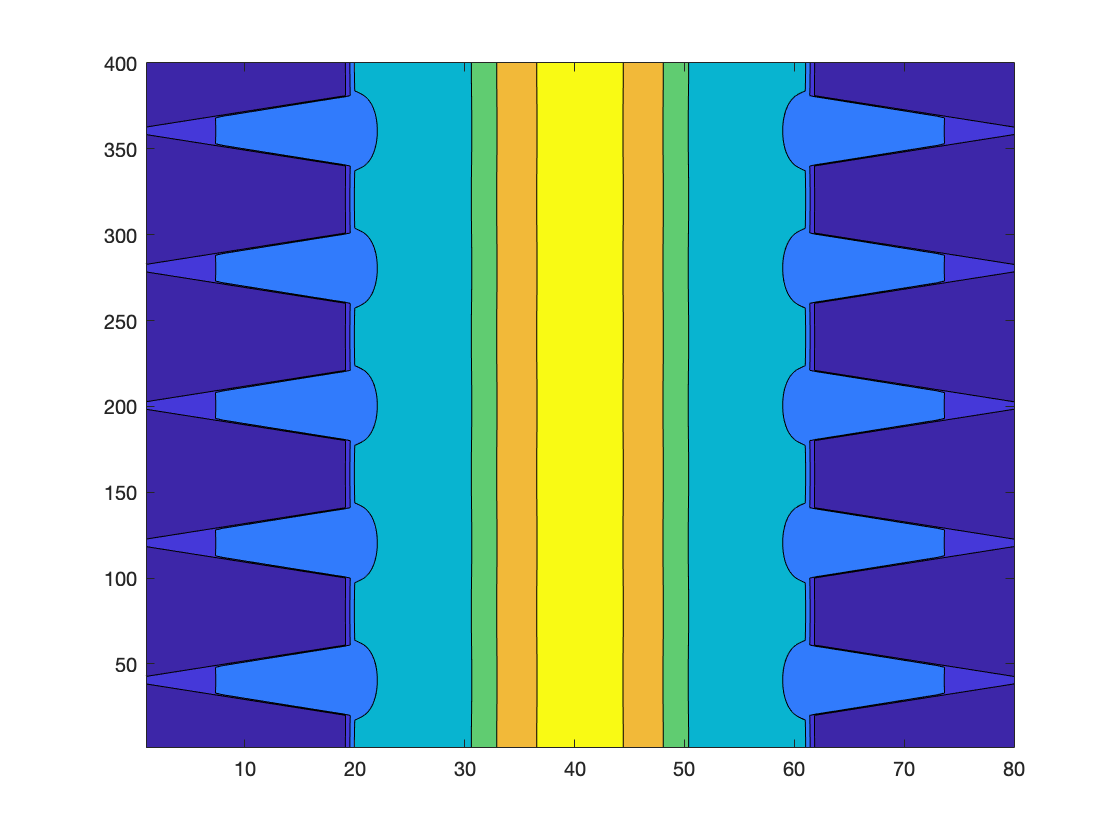

y2=flip(T_final_bonus,2);
z2=[flip(y2,1),flip(T_final_bonus,1);y2,T_final_bonus;flip(y2,1),flip(T_final_bonus,1);y2,T_final_bonus;flip(y2,1),flip(T_final_bonus,1);y2,T_final_bonus;flip(y2,1),flip(T_final_bonus,1);y2,T_final_bonus;flip(y2,1),flip(T_final_bonus,1);y2,T_final_bonus];
contourf(z2)

%finding q off insulation:
q1_1=[];
index = 1;

%looping through the convective boundry nodes
for m=M/2+1:M-1
    q1_1(index)= (T_final_bonus(m,N/2+1)-T_inf)/R_eqi_bound;
    index=index+1;
end
%including the final boundry node of the insulation
q1_1(index+1) = (T_final_bonus(M,N/2+1)-T_inf)/R_eqi_corner;

%Note that q_base is q from insulation
q_base_bonus = sum(q1_1) %this is for one C.V.

q_base_bonus = 0.2991

q_base_total_bonus = 2*12*q_base_bonus %This is for the whole reactor (One C.V. is a half fin and 

q_base_total_bonus = 7.1781

                       %half cylinder. There are six fins and another half
                       %to account for)

                      
%Finding q off fin:
q2_2=[];
n=23;
index = 1;
%Looping through all of the full fin nodes
for m= M/2-1:-1:2
    R_eqf = R_f/(4*pi*(n-2)*dr*dz) + 1/(4*h*pi*(n-2)*dr*dz);
    q2_2(index)=(T_final_bonus(m,n)-T_inf)/R_eqf;
    n=n+1;
    index=index+1;
end

%Including the tip node and trianglar fin node at the insulation face.
q2_2(index) = (T_tip_bonus-T_inf)/R_eqf_tip;
q2_2(index+1) = (T_final_bonus(M/2,N/2+2)-T_inf)/R_eqf_corner;

%Note that q_f is q from fin
q_f_bonus = sum(q2_2) %Just one C.V.

q_f_bonus = 1.0071

q_f_total_bonus = 2*12*q_f_bonus %For the entire reactor

q_f_total_bonus = 24.1714